# Process model summary

## Configuration

close all;
T_low = 15;
T_nominal = 40;
T_high =65;

sigma_low = -1;
sigma_nominal = 1;
sigma_high = 2;

L_low =  0;
L_nominal = 100;
L_high =  1000;

vf_low = 0;
vf_nominal = 0.5; 
vf_high = 1;

## Solubility

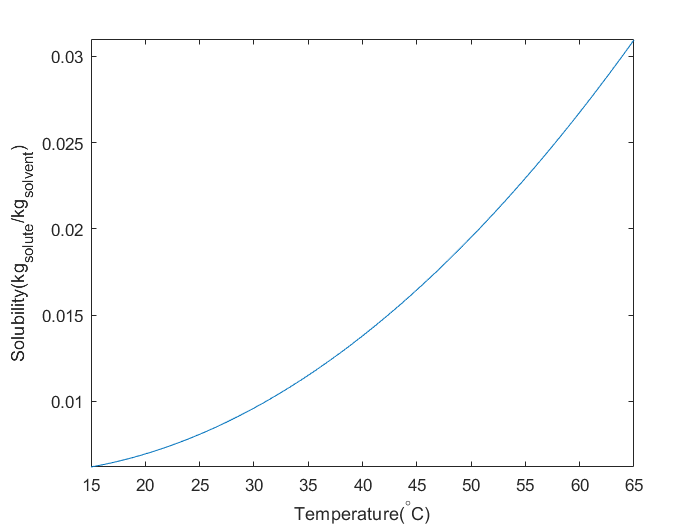

figure;
fplot(@(x)solubility(x+273.15), [T_low T_high]);
xlabel('Temperature(^\circC)');
ylabel('Solubility(kg_{solute}/kg_{solvent})');

At nominal temperature, the solubility is

fprintf("Solubility@ %.2f C = %f kg/kg", T_nominal, solubility(T_nominal+273.15));

Solubility@ 40.00 C = 0.013792 kg/kg

## Growth and dissolution

### Growth rate (um/s) 

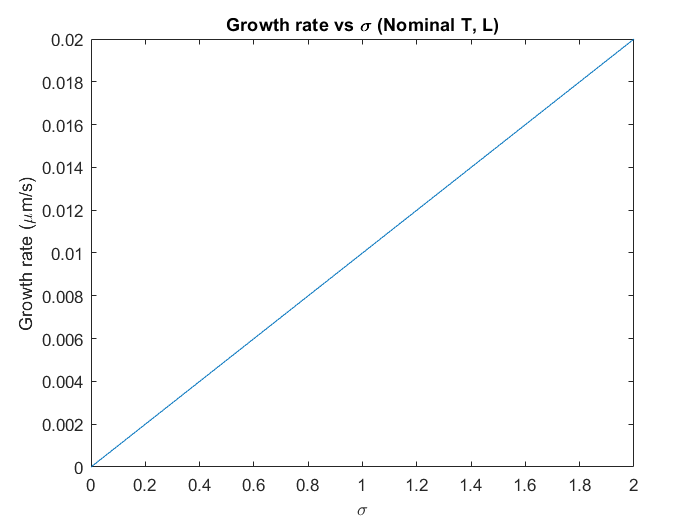

x = linspace(0, sigma_high); 
[GD, ~, ~] = arrayfun(@(xx)kinetics(T_nominal+273.15, xx, vf_nominal), x) ;
figure;
plot(x, GD);
xlabel('\sigma');
ylabel('Growth rate (\mum/s)');
title('Growth rate vs \sigma (Nominal T, L)');

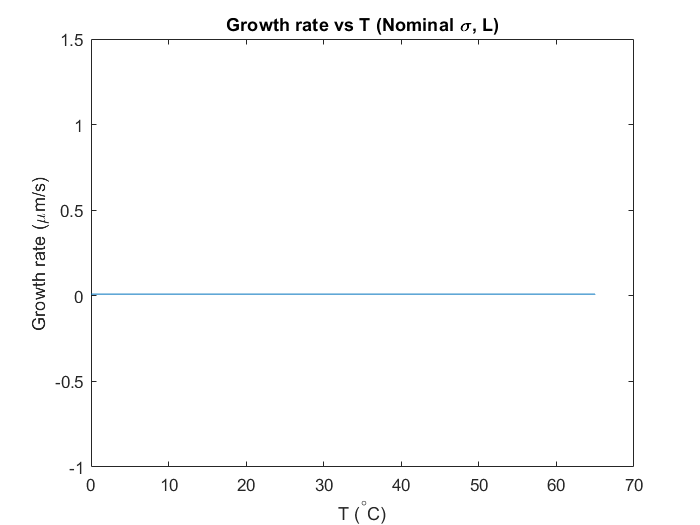

x = linspace(0, T_high); 
[GD, ~, ~] = arrayfun(@(xx)kinetics(xx+273.15, sigma_nominal, vf_nominal), x) ;
figure;
plot(x, GD);
xlabel('T (^\circC)')
ylabel('Growth rate (\mum/s)');
title('Growth rate vs T (Nominal \sigma, L)');

### Dissolution rate (um/s)

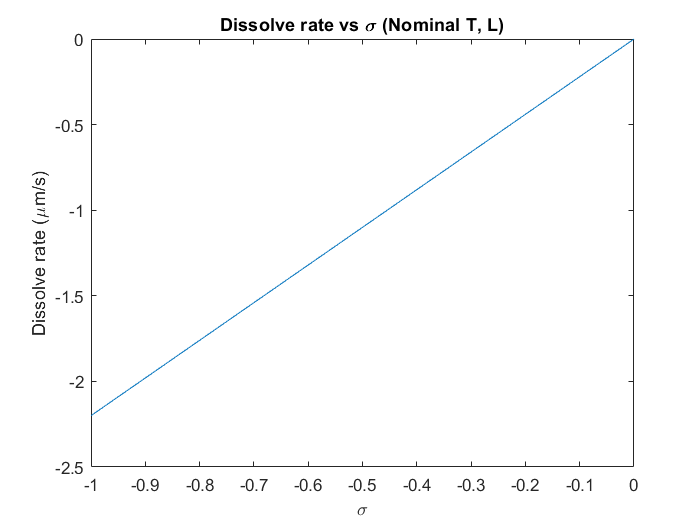

x = linspace(sigma_low, 0); 
[GD, ~, ~] = arrayfun(@(xx)kinetics(T_nominal+273.15, xx, vf_nominal), x) ;
figure;
plot(x, GD);
xlabel('\sigma')
ylabel('Dissolve rate (\mum/s)')
title('Dissolve rate vs \sigma (Nominal T, L)')

## Nucleations

### Primary Nucleation

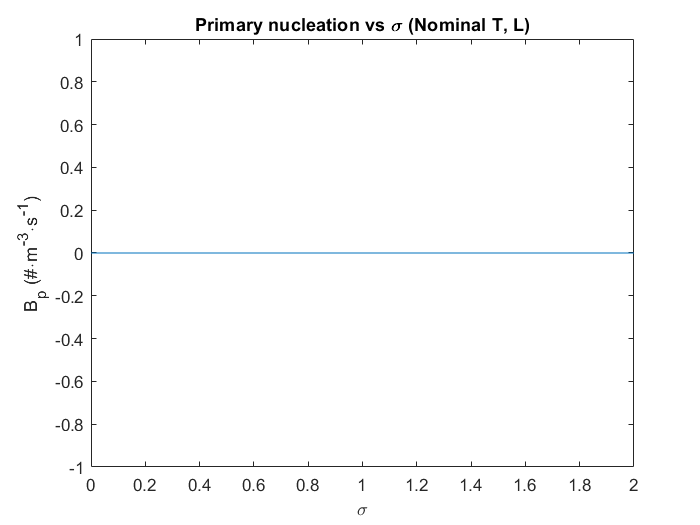

x = linspace(0, sigma_high); 
[~, Bp, ~] = arrayfun(@(xx)kinetics(T_nominal+273.15, xx, vf_nominal), x) ;
figure;
plot(x, Bp);
xlabel('\sigma')
ylabel('B_p (#\cdotm^{-3}\cdots^{-1})')
title('Primary nucleation vs \sigma (Nominal T, L)')

### Secondary Nucleation

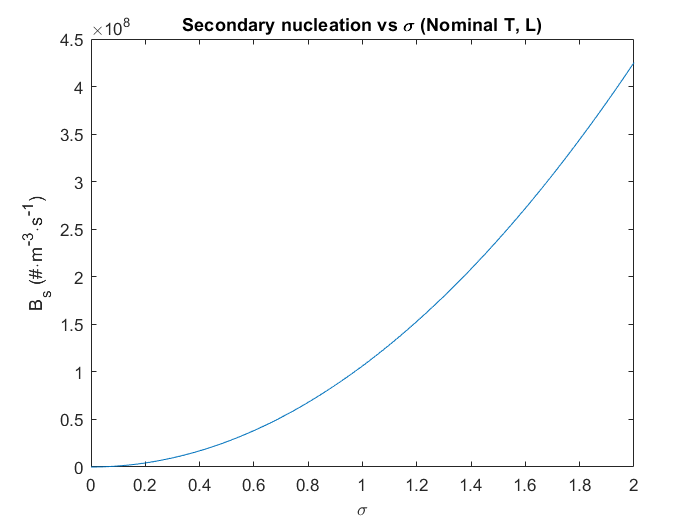

x = linspace(0, sigma_high); 
[~, ~, Bs] = arrayfun(@(xx)kinetics(T_nominal+273.15, xx, vf_nominal), x) ;
figure;
plot(x, Bs);
xlabel('\sigma')
ylabel('B_s (#\cdotm^{-3}\cdots^{-1})')
title('Secondary nucleation vs \sigma (Nominal T, L)')

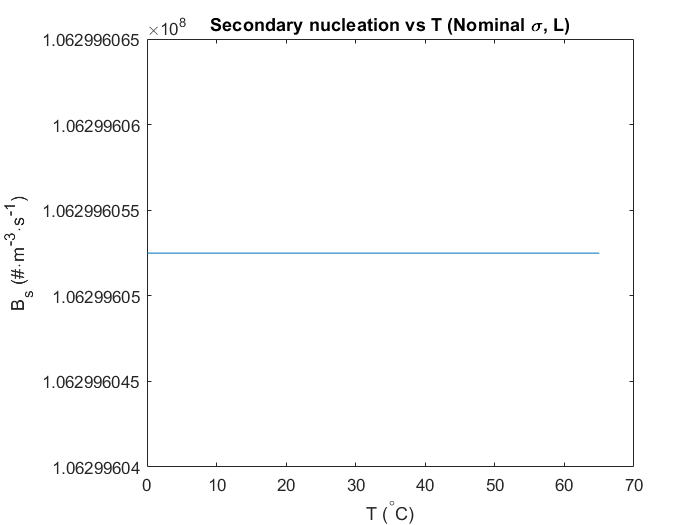

x = linspace(0, T_high); 
[~, ~, Bs] = arrayfun(@(xx)kinetics(xx+273.15, sigma_nominal, vf_nominal), x) ;
figure;
plot(x, Bs);
xlabel('T (^\circC)')
ylabel('B_s (#\cdotm^{-3}\cdots^{-1})')
title('Secondary nucleation vs T (Nominal \sigma, L)')